clear; close all; clc; clf;



%DesignParameters = [a_0, n, sigma_p, gamma_p, cstar, rho_p, mw_air, gamma_air, A_rocket, R_u, ge]
DesignParameters = [0.03,0.35, 0.001, 1.25, 5210, 0.065, 28.97, 1.4, 6.19*pi*6.19, 1545.3, 32.2];

%DesignInputs = [r_i, r_o, l_0, Ngrain, mystery_0, A_t0, m_bal];

% baseline design
DesignInputs = [1, 2.375, 8, 4, 4, 1, 1];

%DesignOutputs = [m_p0, A_tb, t_b, isp_avg, p_cmax, f_max, A_p0A_t0]
DesignOutputs = [0, 0, 0, 0, 0, 0, 0];


x = thrust_coefficient(1.2,100,100)

x = 0.9522

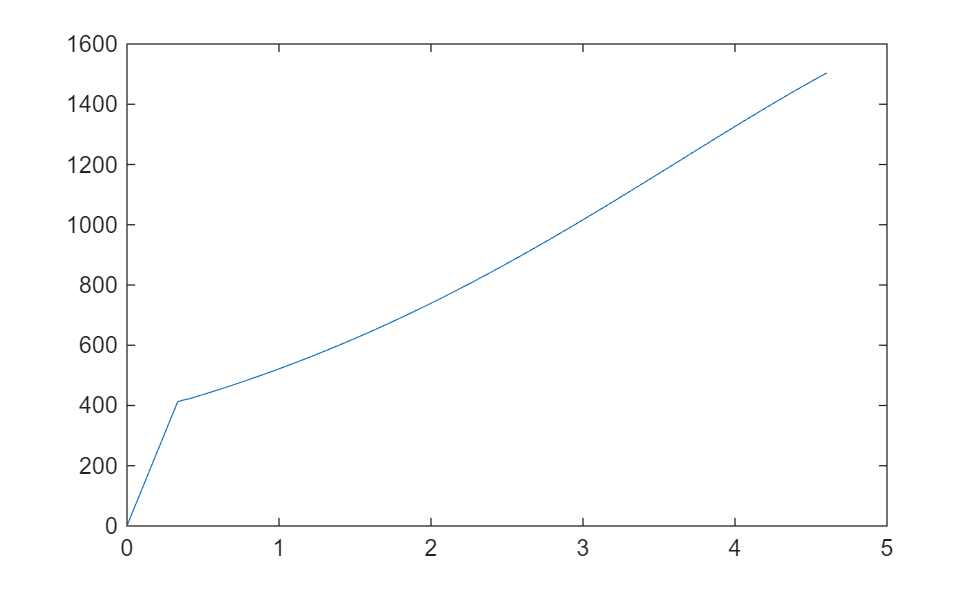

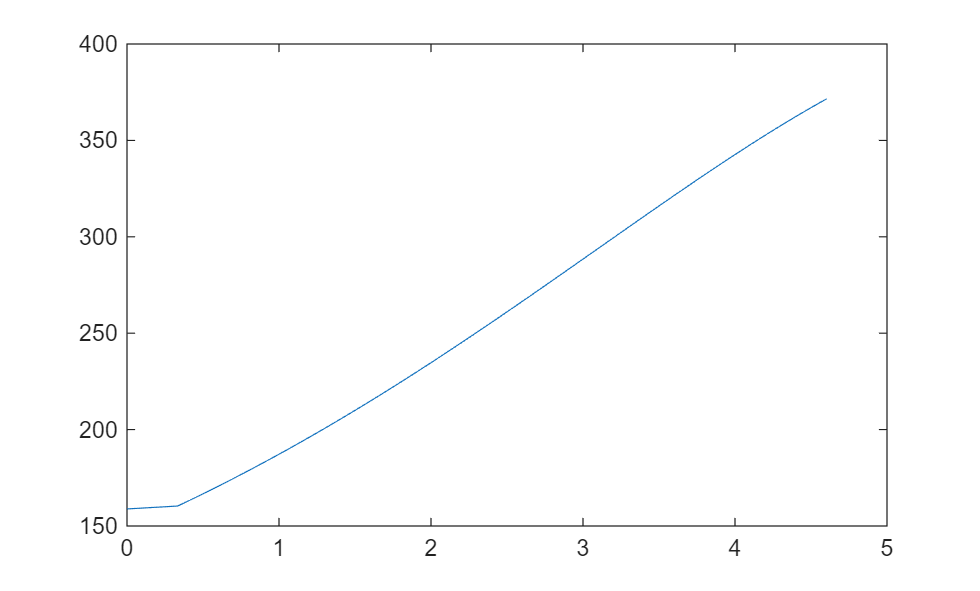

DesignOutputs =   466.5265    1.0060    4.6032


DesignOutputs =   466.5265    1.0060    4.6032




DesignOutputs = rocket(DesignInputs,DesignParameters)





function [DesignOutputs] = rocket(DesignInputs,DesignParameters)

    w_step = 0.01;

    Cd =  [0.15 0.15 0.42 0.25 0.175];
    mCd = [0.00 0.60 1.20 1.80 4.000];

    r_i = DesignInputs(1);
    r_o = DesignInputs(2);
    l_0 = DesignInputs(3);
    Ngrain = DesignInputs(4);
    A_e0 = DesignInputs(5);
    A_t0 = DesignInputs(6);
    m_bal = DesignInputs(7);

    a_0 = DesignParameters(1);
    n = DesignParameters(2);
    sigma_p = DesignParameters(3);
    gamma_p = DesignParameters(4);
    cstar = DesignParameters(5); 
    rho_p = DesignParameters(6);
    mw_air = DesignParameters(7);
    gamma_air = DesignParameters(8);
    A_rocket = DesignParameters(9);
    R_u = DesignParameters(10);
    ge = DesignParameters(11);

    
    if (l_0/2) < (r_o - r_i)
        wmax = l_0/2;
    else
        wmax = r_o - r_i;
    end

    w = 0:w_step:wmax;
    
    A_b = Ngrain * pi .* ((r_o^2 - (r_i+w).^2) + ((r_i+w).^2).*(l_0-2.*w));
    p_c = NaN(size(w)); p_c(1) = 1;         
    A_t = NaN(size(w)); A_t(1) = A_t0;     
    r = NaN(size(w)); r(1) = 1;         
    vel = NaN(size(w)); vel(1) = 0;      
    T_a = NaN(size(w)); T_a(1) = 518;     
    F_t = NaN(size(w)); F_t(1) = 0;        
    mdot = NaN(size(w));                    
    m_r = NaN(size(w)); m_r(1) = m_bal +    Ngrain * (r_o^2 - r_i^2) * pi * l_0 + (l_0+0.125) * Ngrain * 0.25 + 40;
    rho_air = NaN(size(w)); rho_air(1) = 0.07579;
    mach = NaN(size(w)); mach(1) = 0;
    eta = NaN(size(w)); eta(1) = A_t(1)/A_e0;
    time = NaN(size(w)); time(1) = 0;
    dt = NaN(size(w));
    acc = NaN(size(w)); acc(1) = 0;
    height = NaN(size(w)); height(1) = 0;
    p_a = NaN(size(w)); p_a(1) = 14.69241;  
    Isp = NaN(size(w));

    for i = 1:(length(w)-1)

        r(i+1) = a_0 * p_c(i)^n;

        dt(i) = w_step/r(i+1);

        time(i+1) = time(i) + dt(i);

        A_t(i+1) = ( (4/pi) ^ 0.5 + 0.000087 * dt(i) * p_c(i) )^(2) * pi/4;

        p_c(i+1) = (a_0 * rho_p * A_b(i) * cstar/(ge * A_t(i)))^(1/(1-n));

        eta(i+1) = A_t(i)/A_e0;

        mach(i+1) = vel(i)/sqrt(gamma_air * R_u/mw_air * ge * T_a(i));

        acc(i+1) = F_t(i)/m_r(i) - ge - interp1(mCd,Cd,mach(i)) * 0.5 * rho_air(i) * vel(i)^2 * A_rocket/m_r(i);

        vel(i+1) = (acc(i+1) + acc(i))/2 * dt(i);

        height(i+1) = (vel(i+1) + vel(i))/2 * dt(i);

        rho_air(i+1) = 0.00000000001255* height(i)^2 - 0.0000019453*height(i) + 0.07579;

        p_a(i+1) = -4.272981E-14*height(i)^3 + 0.000000008060081*height(i)^2 - 0.0005482655*height(i) + 14.69241;

        F_t(i+1) = p_c(i) * A_t(i) * thrust_coefficient(gamma_p,eta(i),p_c(i)/p_a(i));

        mdot(i+1) =  p_c(i)* A_t(i)/cstar;

        T_a(i+1) = -0.0036*height(i) + 518;

        %        balast mass             mass of the grains           case mass                   baseline mass
        m_r(i+1) = (m_bal +    Ngrain * (r_o^2 - r_i^2) * pi * l_0 + (l_0+0.125) * Ngrain * 0.25 + 40) - mdot(i)*dt(i);

        Isp(i+1) = F_t(i)/(mdot(i)*ge);
  
    end

    figure(1)
    plot(time,p_c)
    figure(2)
    plot(time,A_b)

    DesignOutputs = [Ngrain * (r_o^2 - r_i^2) * pi * l_0 A_t(end) time(end) ]

end


function [cf] = thrust_coefficient(gamma, areaRatio, pcpa)
    
    if isnan(pcpa)
        cf = NaN;
        return
    end

    if isnan(areaRatio)
        cf = NaN;
        return
    end

    f = @(M) (1./M) .* ( (2/(gamma+1)) .* (1 + (gamma-1)/2 .* M.^2) ).^((gamma+1)/(2*(gamma-1))) - areaRatio;
    try
    mach = fzero(f, [1.0001, 50]);
    catch
        cf = 0;
        return
    end

    
    papc = 1/pcpa;
    pepc = (1+ (gamma-1)/2*mach^2)^(-gamma/(gamma-1));
    cf = (2*gamma^2/(gamma-1)*(2/(gamma+1))^((gamma+1)/(gamma-1))*(1-pepc^((gamma-1)/gamma)))^0.5 + (pepc - papc)*areaRatio;
end
